Addpath

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")

Sampling Time, Time Step & Simulation Time

dt=1e-5;
ts=0.008;
SimulationTime=1.0;

Initial Condition

TargetAngle=[pi/2,pi/4,pi/6,pi/3,-pi/6,-pi/2,pi/3]';
StateInitial=[TargetAngle+0.01;zeros(7,1)];

Gains

Kp=0.1*diag([600,600,600,600,250,150,50]);
Kd=0.1*diag([50,50,50,20,20,20,10]);

Time History Matrix

StateTimeHistoryDigital=zeros(7*2,round(SimulationTime/dt)+1);
SampledStateTimeHistoryDigital=zeros(7*2,floor(SimulationTime/ts));
TorqueTimeHistoryDigital=zeros(7,round(SimulationTime/dt)+1);
StateTimeHistoryDigital(:,1)=StateInitial;
TimeSpan=0:dt:SimulationTime;
SampledStateTimeHistoryDigital(:,1)=StateInitial;
TorqueTimeHistoryDigital(:,1)=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);
TorqueTimeHistoryContinuous=zeros(7,round(SimulationTime/dt)+1);

Solver Option

option=odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

For $t\in[0,t_s]$, torque $\tau$ is computed with state at $t=0$, the $1$st column of StateTimeHistoryDigital.

For $t\in[t_s,2t_s]$, torque $\tau$ is computed with state at $t=0$, the $1$st column of StateTimeHistoryDigital.

For $t\in[2t_s,3t_s]$, torque $\tau$ is computed with state at $t=t_s$, the $2$nd column of StateTimeHistoryDigital.


$$\vdots$$


For $t\in[k t_s,(k+1)t_s]$, torque $\tau$ is computed with state at $t=(k-1)t_s$, the $k$th column of StateTimeHistoryDigital.

### Continuous Time Case

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,PDTorque(Kp,Kd,State,TargetAngle)),TimeSpan,StateInitial,option);
StateTimeHistoryContinuous=State';
for i=1:round(SimulationTime/dt)+1
    TorqueTimeHistoryContinuous(:,i)=PDTorque(Kp,Kd,StateTimeHistoryContinuous(:,i),TargetAngle);
end
toc

历时 3.951757 秒。


### Digital Feedback Control Case

Simulation

tic
bar=waitbar(0,"Start Simulation");
for i=1:floor(SimulationTime/ts)
    SampledStateTimeHistoryDigital(:,i)=StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1);
    if i==1
        Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);
    else
        Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,i-1),TargetAngle);
    end
    TorqueTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=repmat(Tau,1,round(ts/dt));
    [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan((i-1)*round(ts/dt)+1:i*round(ts/dt)+1),StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1),option);
    StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=State(2:end,:)';
    str=[num2str(100*i/floor(SimulationTime/ts)),'%',' Finished'];
    waitbar(i/floor(SimulationTime/ts),bar,str);
end
waitbar(1,bar,"Handling Final Interval");
if floor(SimulationTime/ts)~=ceil(SimulationTime/ts)
    [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan(floor(SimulationTime/ts)*round(ts/dt)+1:end),StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+1),option);
    StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=State(2:end,:)';
    TorqueTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=repmat(Tau,1,round(mod(SimulationTime,ts)/dt));
end
delete(bar);
toc

历时 33.368142 秒。


### Delay Control Case

Controller

Controller=@(State)PDTorque(Kp,Kd,State,TargetAngle);

History Solution

history=@(t)get_HistorySolution(t,StateInitial);

Simulation

tic
option=ddeset('RelTol', 1e-12, 'AbsTol', 1e-12,"InitialStep",dt,"MaxStep",1.5*dt);
sol=dde23(@(t,State,StateDelayed)DDE(t,State,StateDelayed,Controller),1.5*ts,history,TimeSpan,option);
toc

历时 446.744494 秒。


Show Time Steps

disp("Simulation time steps: "+num2str(length(sol.x)))

Simulation time steps: 100108


disp("Visualization time steps: "+num2str(length(TimeSpan)))

Visualization time steps: 100001


Collect Data for Visualization

StateTimeHistoryDelay=deval(sol,TimeSpan,1:14);
eTimeHistoryContinuous=StateTimeHistoryContinuous(1:7,:)-TargetAngle;
eTimeHistoryDelay=StateTimeHistoryDelay(1:7,:)-TargetAngle;
eTimeHistoryDigital=StateTimeHistoryDigital(1:7,:)-TargetAngle;

### Visualization for Continuous Time Control

disp("Continuous Time Control")

Continuous Time Control


$e-t$ Diagram

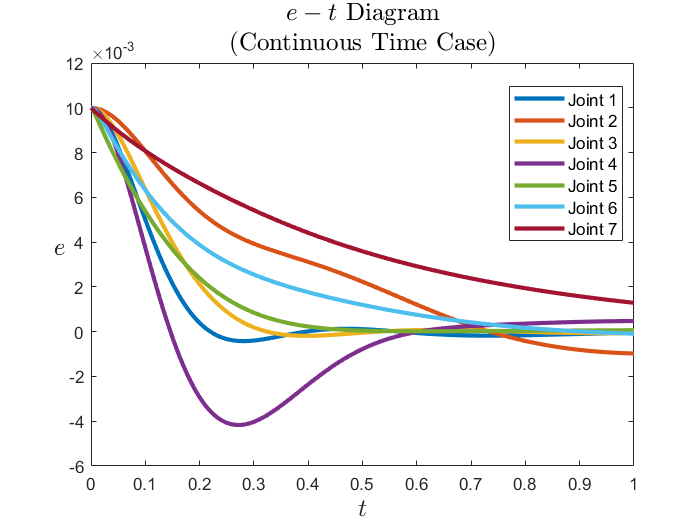

plot(TimeSpan,eTimeHistoryContinuous,"LineWidth",2.5)
title(["$$e-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

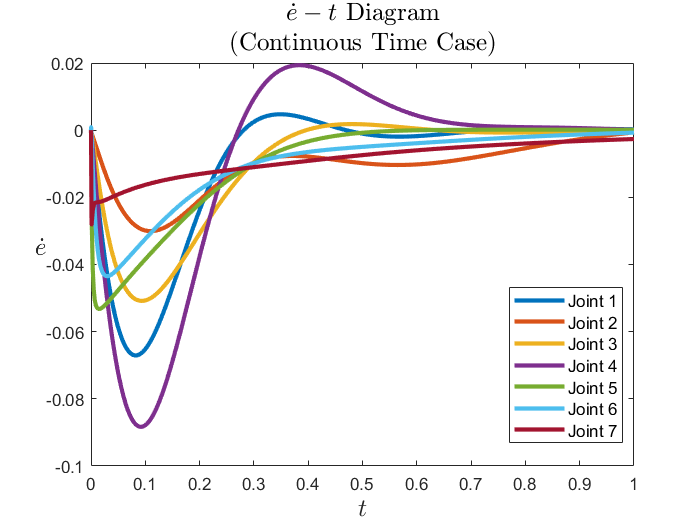

plot(TimeSpan,StateTimeHistoryContinuous(8:14,:),"LineWidth",2.5)
title(["$$\dot{e}-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\tau-t$ Diagram

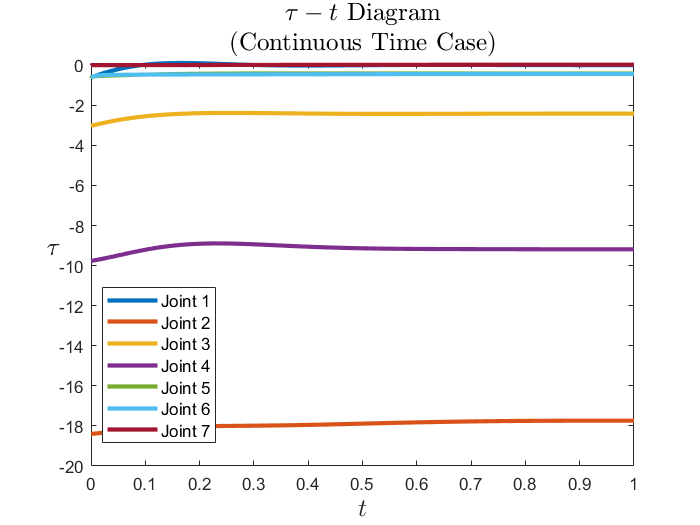

plot(TimeSpan,TorqueTimeHistoryContinuous,"LineWidth",2.5)
title(["$$\tau-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

Phase Portrait

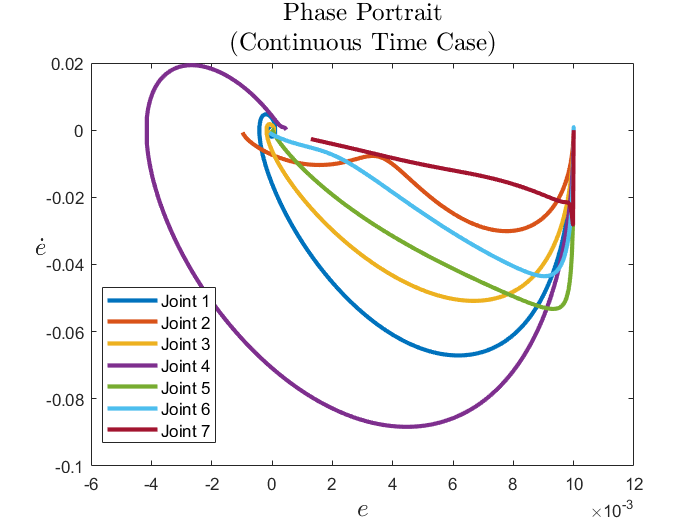

plot(eTimeHistoryContinuous(1,:),StateTimeHistoryContinuous(8,:),"LineWidth",2.5)
hold on
for i=2:7
    plot(eTimeHistoryContinuous(i,:),StateTimeHistoryContinuous(7+i,:),"LineWidth",2.5)
end
hold off
title(["Phase Portrait","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$e$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

### Visualization for Digital Feedback Control

disp("Digital Feedback Control")

Digital Feedback Control


$e-t$ Diagram

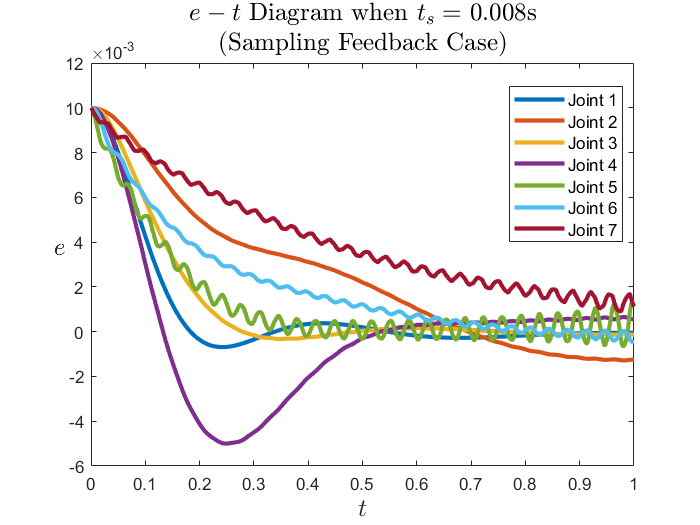

plot(TimeSpan,eTimeHistoryDigital,"LineWidth",2.5)
title(["$$e-t$$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

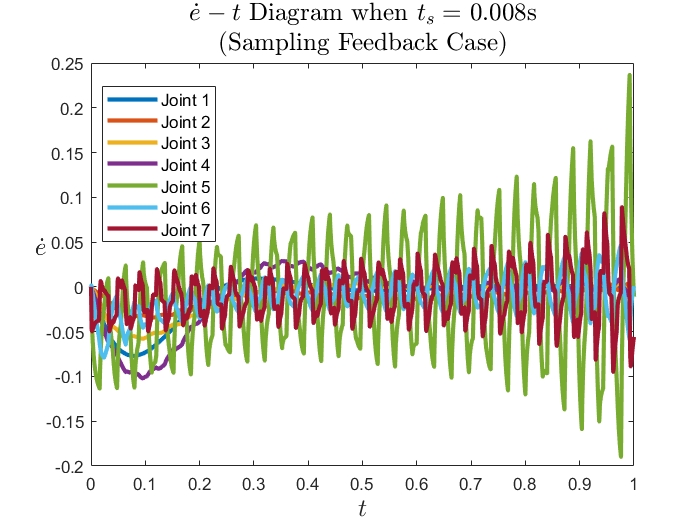

plot(TimeSpan,StateTimeHistoryDigital(8:14,:),"LineWidth",2.5)
title(["$$ \dot{e}-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\tau-t$ Diagram

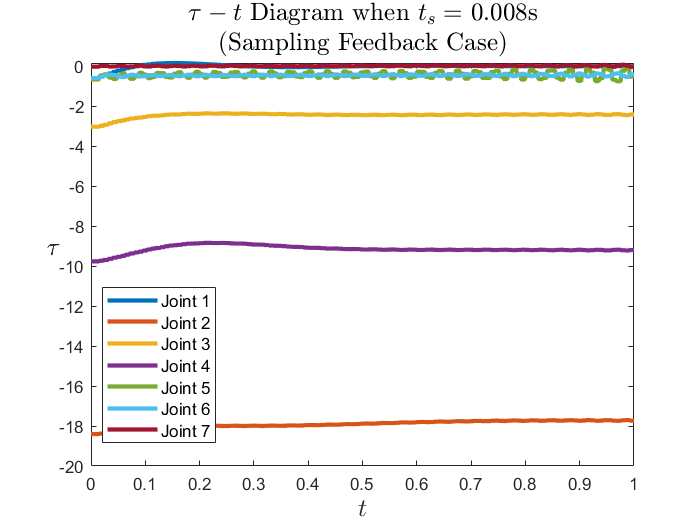

plot(TimeSpan,TorqueTimeHistoryDigital,"LineWidth",2.5)
title(["$$ \tau-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

Phase Portrait

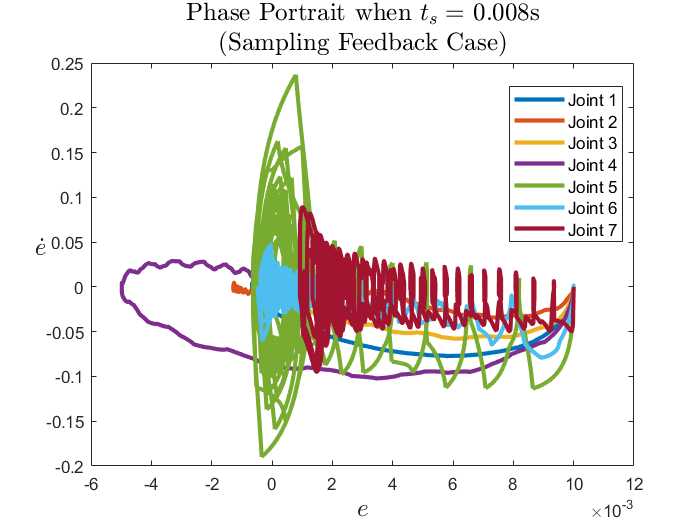

plot(eTimeHistoryDigital(1,:),StateTimeHistoryDigital(8,:),"LineWidth",2.5)
hold on
for i=2:7
    plot(eTimeHistoryDigital(i,:),StateTimeHistoryDigital(7+i,:),"LineWidth",2.5)
end
hold off
title(["Phase Portrait when $$t_s=$$ "+num2str(ts)+"s","(Sampling Feedback Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$e$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

### Visualization for Delayed Control

disp("Delayed Control")

Delayed Control


$e-t$ Diagram

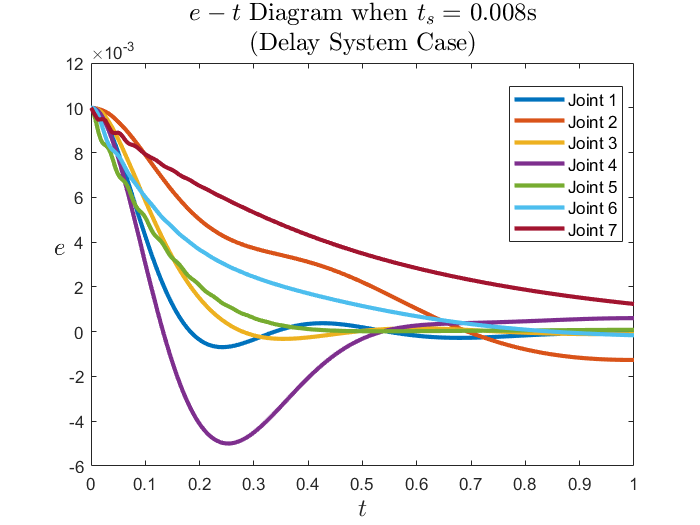

plot(TimeSpan,eTimeHistoryDelay,"LineWidth",2.5)
title(["$$ e-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

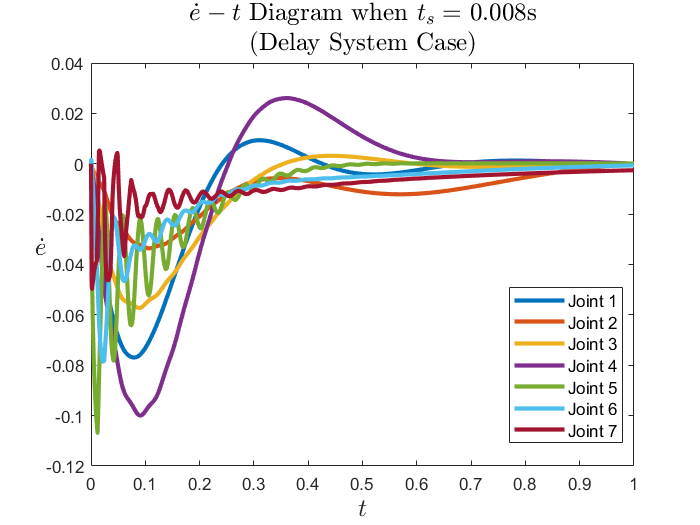

plot(TimeSpan,StateTimeHistoryDelay(8:14,:),"LineWidth",2.5)
title(["$$ \dot{e}-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

Phase Portrait

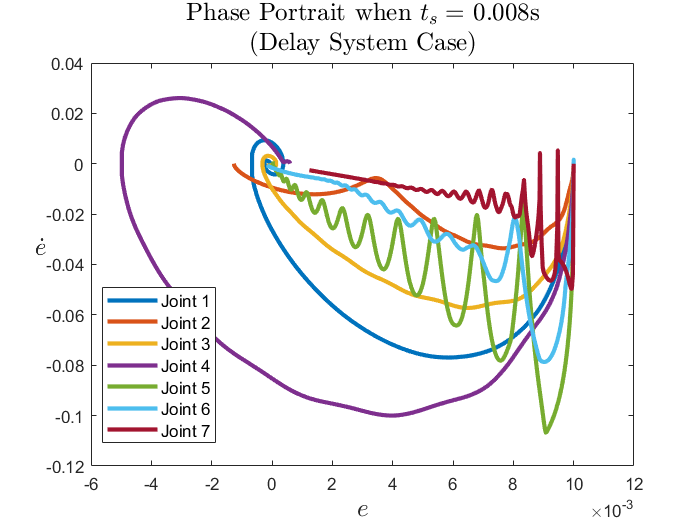

plot(eTimeHistoryDelay(1,:),StateTimeHistoryDelay(8,:),"LineWidth",2.5)
hold on
for i=2:7
    plot(eTimeHistoryDelay(i,:),StateTimeHistoryDelay(7+i,:),"LineWidth",2.5)
end
hold off
title(["Phase Portrait when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$e$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Joint 3","Joint 4","Joint 5","Joint 6","Joint 7","Fontsize",10,"Location","best")

MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocContinuous=panda.fkine(StateTimeHistoryContinuous(1:7,:)').transl';
EndEffectorLocDigital=panda.fkine(StateTimeHistoryDigital(1:7,:)').transl';
EndEffectorLocDelay=panda.fkine(StateTimeHistoryDelay(1:7,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

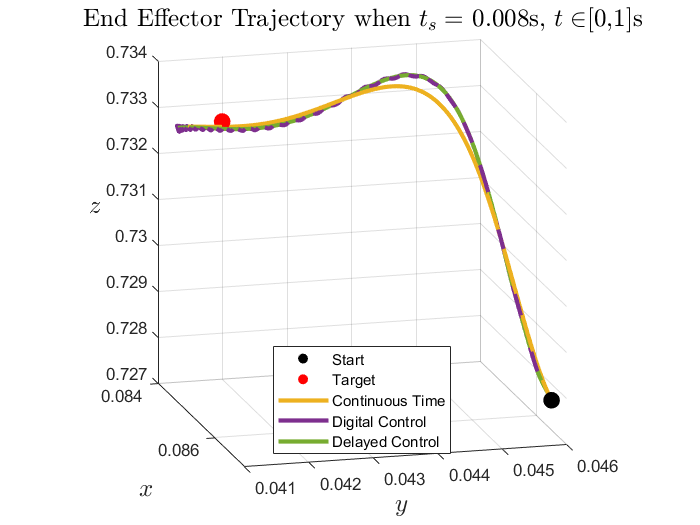

scatter3(EndEffectorLocDigital(1,1),EndEffectorLocDigital(2,1),EndEffectorLocDigital(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"Red","filled","o")
plot3(EndEffectorLocContinuous(1,:),EndEffectorLocContinuous(2,:),EndEffectorLocContinuous(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDigital(1,:),EndEffectorLocDigital(2,:),EndEffectorLocDigital(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDelay(1,:),EndEffectorLocDelay(2,:),EndEffectorLocDelay(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory when $$t_s=$$ "+num2str(ts)+ ...
    "s, $$t \in$$[0,"+num2str(SimulationTime)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Continuous Time","Digital Control","Delayed Control","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
grid on

End Effector Error Visualization

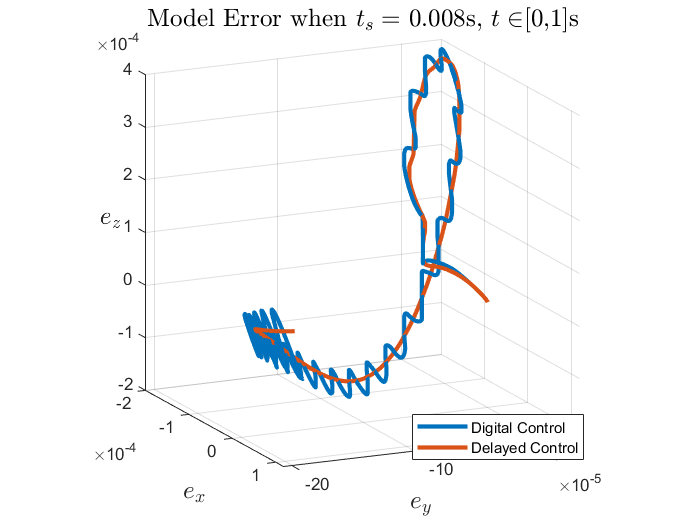

plot3(EndEffectorLocDigital(1,:)-EndEffectorLocContinuous(1,:), ...
    EndEffectorLocDigital(2,:)-EndEffectorLocContinuous(2,:), ...
    EndEffectorLocDigital(3,:)-EndEffectorLocContinuous(3,:),"LineWidth",2.5)
hold on
plot3(EndEffectorLocDelay(1,:)-EndEffectorLocContinuous(1,:), ...
    EndEffectorLocDelay(2,:)-EndEffectorLocContinuous(2,:), ...
    EndEffectorLocDelay(3,:)-EndEffectorLocContinuous(3,:),"LineWidth",2.5)
hold off
pbaspect([1 1 1])
xlabel("$$e_x$$","Interpreter","latex","FontSize",15)
ylabel("$$e_y$$","Interpreter","latex","FontSize",15)
zlabel("$$e_z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
legend("Digital Control","Delayed Control","Location","best")
title("Model Error when $$t_s=$$ "+num2str(ts)+ ...
    "s, $$t \in$$[0,"+num2str(SimulationTime)+"]s", ...
    "FontSize",15,"Interpreter","latex")
view(65,15)
grid on

End Effector Error Time History

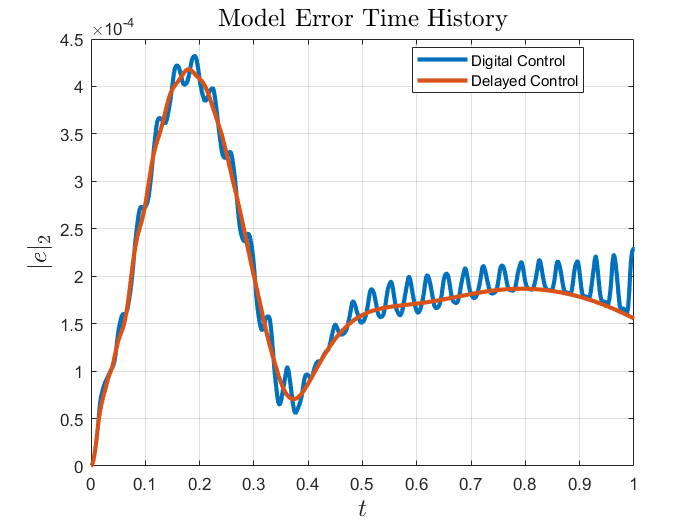

EndEffectorErrorDigital=zeros(size(TimeSpan));
EndEffectorErrorDelay=zeros(size(TimeSpan));
for i=1:length(TimeSpan)
    EndEffectorErrorDigital(i)=norm(EndEffectorLocDigital(:,i)-EndEffectorLocContinuous(:,i));
    EndEffectorErrorDelay(i)=norm(EndEffectorLocDelay(:,i)-EndEffectorLocContinuous(:,i));    
end
plot(TimeSpan,EndEffectorErrorDigital,"LineWidth",2.5)
hold on
plot(TimeSpan,EndEffectorErrorDelay,"LineWidth",2.5)
hold off
title("Model Error Time History","FontSize",15,"Interpreter","latex")
legend("Digital Control","Delayed Control","Location","best")
xlabel("$$t$$","Interpreter","latex","FontSize",15)
ylabel("$$|e|_2$$","Interpreter","latex","FontSize",15)
grid on